% Parameters
folderPath = 'third_test';        % Path to the folder containing audio files
Fs = 44100;                       % Sampling rate (Hz), adjust if needed
numLevels = 3;                    % Number of volume levels
samplesPerLevel = 5;              % Number of samples per volume level
cutoffFreq = 1500;                % High-pass filter cutoff frequency (Hz)

% Design a High-Pass Filter
hpFilter = designfilt('highpassfir', ...
                      'StopbandFrequency', cutoffFreq - 500, ...
                      'PassbandFrequency', cutoffFreq, ...
                      'StopbandAttenuation', 60, ...
                      'PassbandRipple', 1, ...
                      'SampleRate', Fs);

% Loop Through Each Volume Level

% Create a New Figure for Each Volume Level
figure;
hold on;

% Loop Through Each Sample in the Current Volume Level
for sample = 1:samplesPerLevel
    % Generate the Full File Path
    fileName = sprintf('sample%d_record.wav', sample)
    filePath = fullfile(folderPath, fileName);
    
    % Check if the File Exists
    if ~isfile(filePath)
        fprintf('File "%s" not found. Skipping...\n', filePath);
        continue;
    end
    
    % Load the Audio File
    [signal, Fs] = audioread(filePath);
    
    % Apply High-Pass Filter
    filteredSignal = filtfilt(hpFilter, signal); % Zero-phase filtering
    
    % Create a Time Vector
    time = (0:length(filteredSignal)-1) / Fs;
    
    % Plot Filtered Signal
    plot(time, filteredSignal, 'DisplayName', sprintf('Sample %02d', sample));
end

fileName = 'sample1_record.wav'

fileName = 'sample2_record.wav'

fileName = 'sample3_record.wav'

fileName = 'sample4_record.wav'

fileName = 'sample5_record.wav'

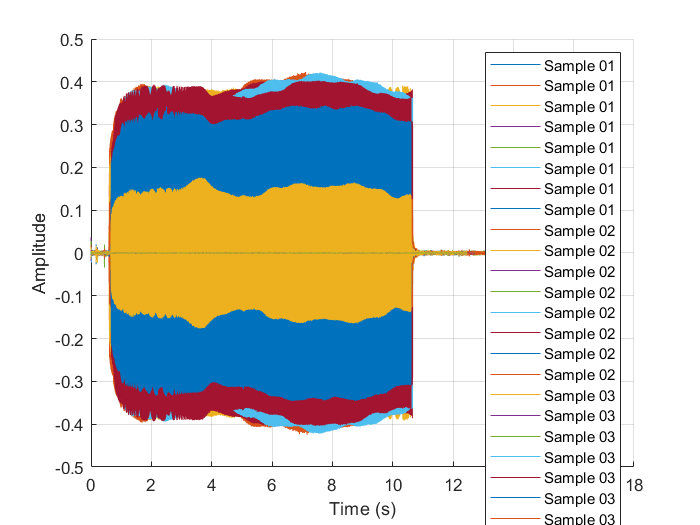


% Add Labels, Title, and Legend
xlabel('Time (s)');
ylabel('Amplitude');
%title(sprintf('High-Pass Filtered Signals for Volume Level %d', level));
legend('show');
grid on;
hold off;

% Parameters
filePath = 'third_test/sample1_record.wav'; % Path to your audio file
Fs = 44100;                                  % Sampling rate (Hz), adjust if needed
cutoffFreq = 2000;                           % High-pass filter cutoff frequency (Hz)

% Design a High-Pass Filter
hpFilter = designfilt('highpassfir', ...
                      'StopbandFrequency', cutoffFreq - 500, ...
                      'PassbandFrequency', cutoffFreq, ...
                      'StopbandAttenuation', 60, ...
                      'PassbandRipple', 1, ...
                      'SampleRate', Fs);

% Check if the File Exists
if ~isfile(filePath)
    error('File "%s" not found. Please check the file path.', filePath);
end

% Load the Audio File
[signal, Fs] = audioread(filePath);

% Apply High-Pass Filter
filteredSignal = filtfilt(hpFilter, signal); % Zero-phase filtering

% Compute FFT of Filtered Signal
N = length(filteredSignal);
fftFiltered = abs(fft(filteredSignal)) / N; % Magnitude of FFT
frequencies = (0:N/2-1) * (Fs / N);         % Frequency vector

% Create a Time Vector
time = (0:length(filteredSignal)-1) / Fs;

% Plot Time Domain and Frequency Domain
figure;

% Time Domain Plot
subplot(2, 1, 1);
plot(time, filteredSignal);
xlabel('Time (s)');
ylabel('Amplitude');
title('High-Pass Filtered Signal - Time Domain');
legend;
grid on;

% Frequency Domain Plot
subplot(2, 1, 2);
plot(frequencies, fftFiltered(1:N/2));

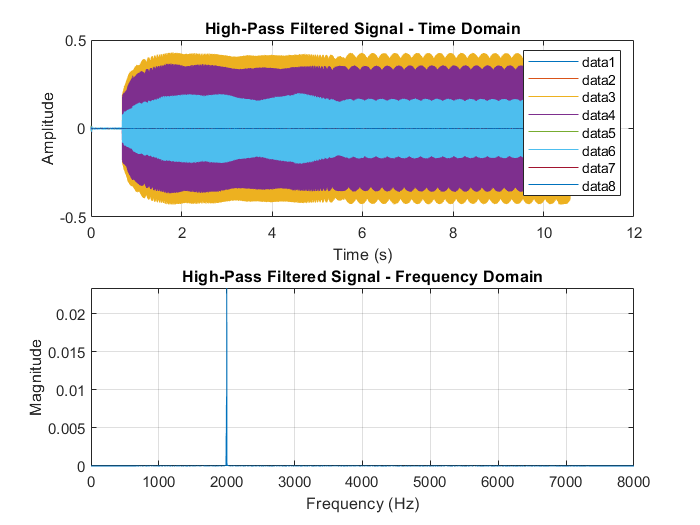

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('High-Pass Filtered Signal - Frequency Domain');
grid on;

% Save the Figure (Optional)
saveas(gcf, 'Filtered_Signal_Time_Frequency.png');

% Load the audio file
[signal, Fs] = audioread('third_test/sample1_record.wav');

% Determine the number of channels
[numSamples, numChannels] = size(signal);

% Display the result
if numChannels == 1
    fprintf('The audio file is mono (1 channel).\n');
elseif numChannels == 2
    fprintf('The audio file is stereo (2 channels).\n');
else
    fprintf('The audio file has %d channels.\n', numChannels);
end

The audio file has 8 channels.


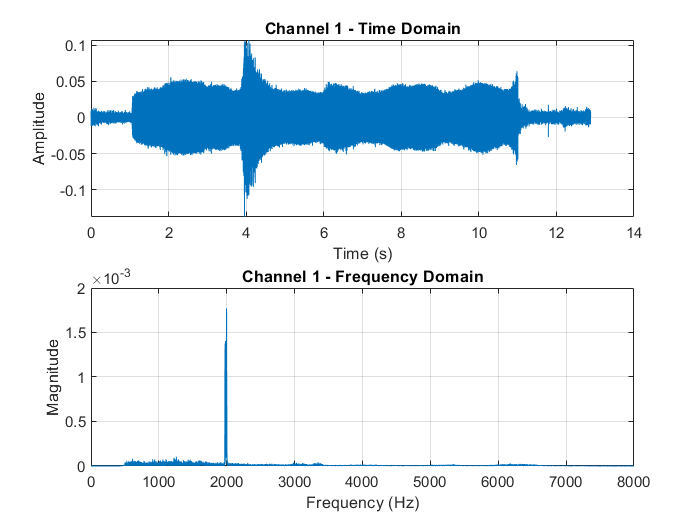

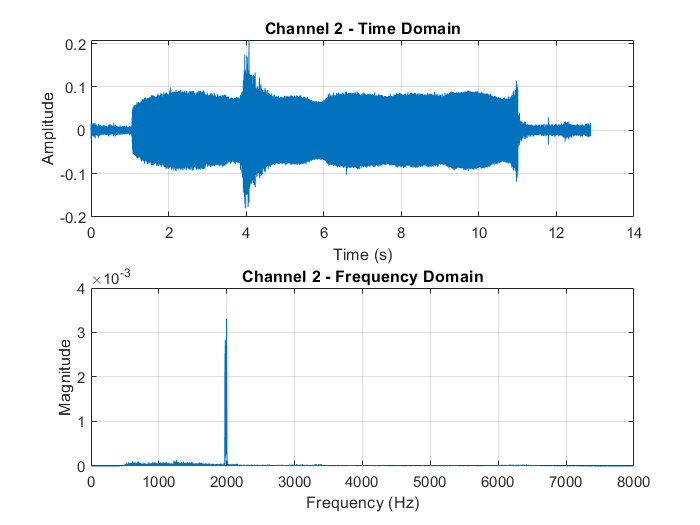

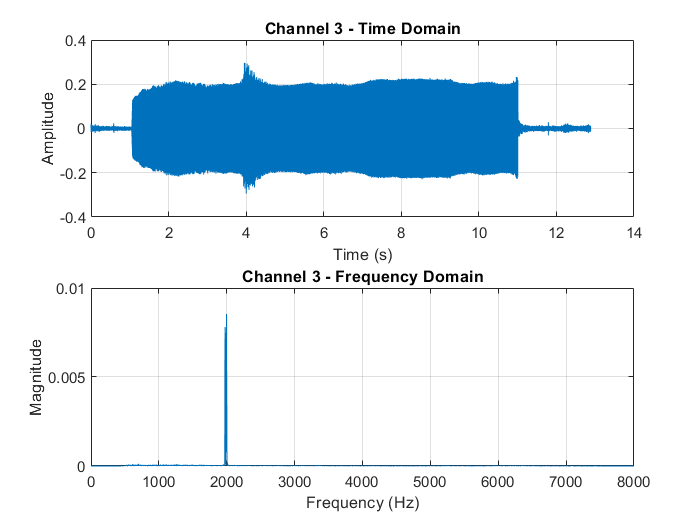

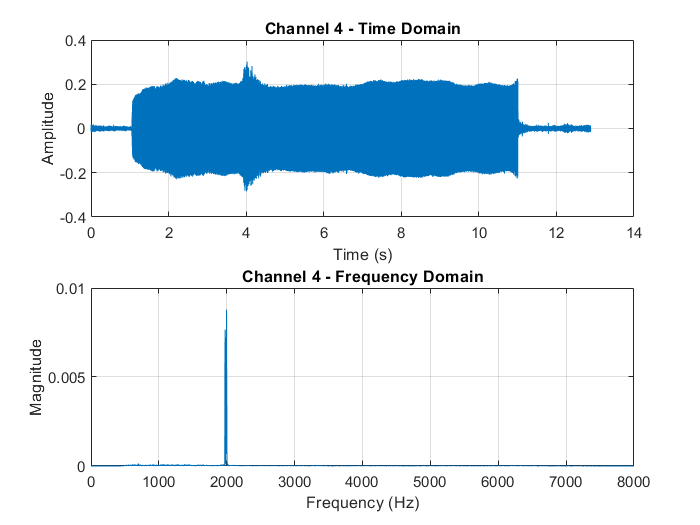

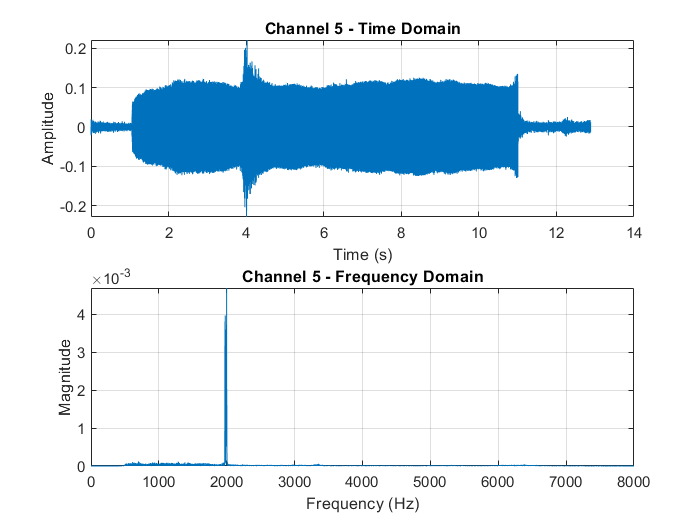

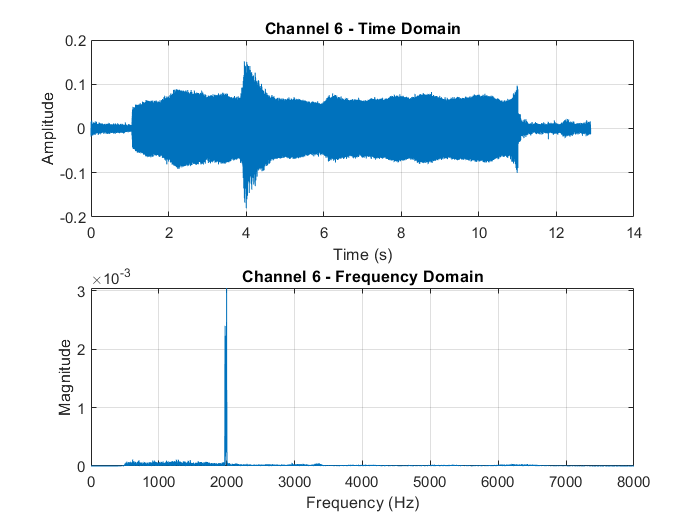

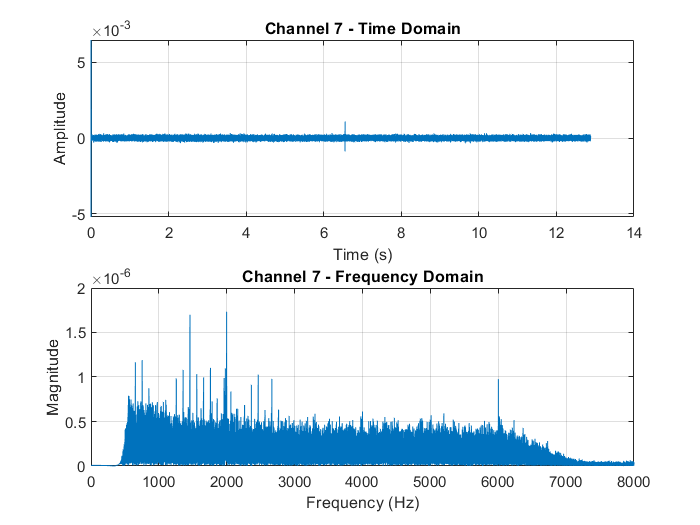

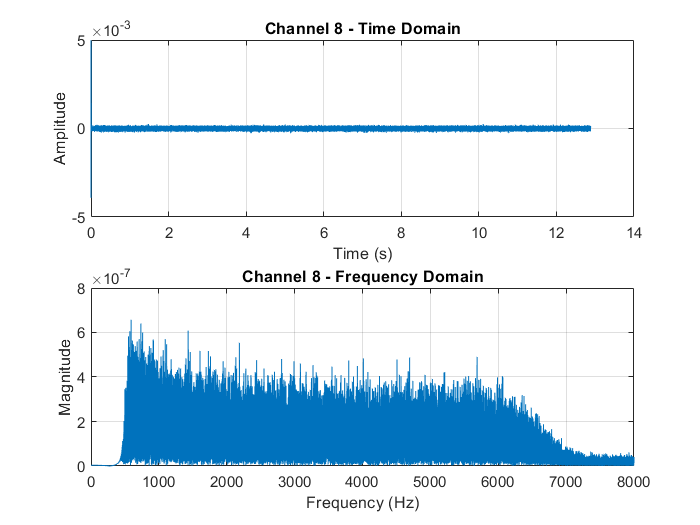

% Parameters
filePath = 'second_test/sample01_record.wav'; % Path to your audio file
cutoffFreq = 1500;                           % High-pass filter cutoff frequency (Hz)

% Design a High-Pass Filter
Fs = 44100; % Sampling rate (adjust if necessary)
hpFilter = designfilt('highpassfir', ...
                      'StopbandFrequency', cutoffFreq - 500, ...
                      'PassbandFrequency', cutoffFreq, ...
                      'StopbandAttenuation', 60, ...
                      'PassbandRipple', 1, ...
                      'SampleRate', Fs);

% Load the Audio File
[signal, Fs] = audioread(filePath);
[numSamples, numChannels] = size(signal); % Get number of samples and channels

% Process Each Channel Separately
for ch = 1:numChannels
    % Extract Channel Data
    channelSignal = signal(:, ch);
    
    % Apply High-Pass Filter
    filteredSignal = filtfilt(hpFilter, channelSignal); % Zero-phase filtering

    % Compute Time Vector
    time = (0:length(filteredSignal)-1) / Fs;

    % Compute FFT of Filtered Signal
    N = length(filteredSignal);
    fftFiltered = abs(fft(filteredSignal)) / N; % Magnitude of FFT
    frequencies = (0:N/2-1) * (Fs / N);         % Frequency vector

    % Create a New Figure for Each Channel
    figure;

    % Time Domain Plot
    subplot(2, 1, 1);
    plot(time, filteredSignal);
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(['Channel ', num2str(ch), ' - Time Domain']);
    grid on;

    % Frequency Domain Plot
    subplot(2, 1, 2);
    plot(frequencies, fftFiltered(1:N/2));
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    title(['Channel ', num2str(ch), ' - Frequency Domain']);
    grid on;

    % Save Figure (Optional)
    saveas(gcf, ['Channel_' num2str(ch) '_FilteredOutput.png']); % Save the plot as an image
end